% load data
clear
load('Assignment_Data_SC42145.mat');

define Delta

%Delta = blkdiag(ultidyn('D_i1',[1,1], 'bound',1), ultidyn('D_i2',[1,1], 'bound',1),...
%                ultidyn('D_o1',[1,1], 'bound',1),ultidyn('D_o2',[1,1], 'bound',1));

Delta = [ultidyn('D_i1',[1,1], 'bound',1),0,0,0;
        0, ultidyn('D_i2',[1,1], 'bound',1),0,0;
        0,0,ultidyn('D_o1',[1,1], 'bound',1),0;
        0,0,0,ultidyn('D_o2',[1,1], 'bound',1)];

%load plant
load("P_q4.mat")
%P = load

Wu.InputName = {'u_g(1)'; 'u_g(2)'};
Wu.InputName = {'u_(1)'; 'u_(2)'};
Wu.OutputName = {'z_1(1)'; 'z_1(2)'};
Wp.InputName = {'y(1)'; 'y(2)'};
Wp.OutputName = {'z_2(1)'; 'z_2(2)'};
Wi.InputName = {'u_(1)'; 'u_(2)'};
Wi.OutputName = {'y_1d(1)'; 'y_1d(2)'};
Wo.InputName = {'y_g(1)'; 'y_g(2)'};
Wo.OutputName = {'y_2d(1)';'y_2d(2)'};
P.OutputName = {'y_1d(1)';'y_1d(2)';'y_2d(1)';'y_2d(2)';'z_1(1)'; 'z_1(2)';'z_2(1)'; 'z_2(2)';'v_(1)';'v_(2)'};
P.InputName = {'u_1d(1)'; 'u_1d(2)'; 'u_2d(1)'; 'u_2d(2)'; 'w_(1)'; 'w_(2)'; 'u_(1)'; 'u_(2)'};

P_w_D_OutputName = {'z_1(1)'; 'z_1(2)';'z_2(1)'; 'z_2(2)';'v_(1)';'v_(2)'};
P_w_D_InputName = {'w_(1)'; 'w_(2)'; 'u_(1)'; 'u_(2)'};

Delta.OutputName = {'u_1d(1)'; 'u_1d(2)'; 'u_2d(1)'; 'u_2d(2)';};
Delta.InputName = {'y_1d(1)'; 'y_1d(2)'; 'y_2d(1)';'y_2d(2)'};

P_w_D = connect(Delta, P, P_w_D_InputName, P_w_D_OutputName);


equivalent:

sum_plant_output = sumblk('y=y_g+u_2d+w_',2);
sum_plant_input = sumblk('u_g = u_+u_1d',2);
y_to_v = sumblk('v_=-y',2);

G = FWT(1:2,1:2);
G.InputName = {'u_g(1)'; 'u_g(2)'};
G.OutputName = {'y_g(1)'; 'y_g(2)'};
%P_w_D = connect(G, Delta, sum_plant_input, sum_plant_output, Wi, Wo, Wu, Wp, y_to_v,  P_w_D_InputName, P_w_D_OutputName);


Question 2.3

clf
figure()
ss_plot_P_OutputName = {'y(1)'; 'y(2)'};
ss_plot_P_InputName = {'u_(1)'; 'u_(2)'};
sum_plant_output_without_w = sumblk('y=y_g+u_2d',2);
ss_plot_P = connect(G, Delta, sum_plant_input, sum_plant_output_without_w, Wi, Wo, ss_plot_P_InputName, ss_plot_P_OutputName);

warning off;
subplot(2,2,1);
w = {10^-1; 10^4};
ticks = [1e-1 1e0 1e1 1e2 1e3 1e4]

ticks = 	1.0e+04 *

    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


sigma(ss_plot_P(1,1),w); hold on; latex_sigma(FWT(1,1), w, "red")
title("$\beta \to \Omega$", "interpreter", "latex"); xticks(ticks)

subplot(2,2,2);
sigma(ss_plot_P(1,2),w); hold on; latex_sigma(FWT(1,2), w, 'red')
title("$\tau_e \to \Omega$", "interpreter", "latex"); xticks(ticks)

subplot(2,2,3); 
sigma(ss_plot_P(2,1),w); hold on; latex_sigma(FWT(2,1), w,'red')
title("$\beta \to z$", "interpreter", "latex"); xticks(ticks)

subplot(2,2,4);
sigma(ss_plot_P(2,2),w); hold on; latex_sigma(FWT(2,2),w, 'red')
title("$\tau_e \to z$", "interpreter", "latex"); xticks(ticks)

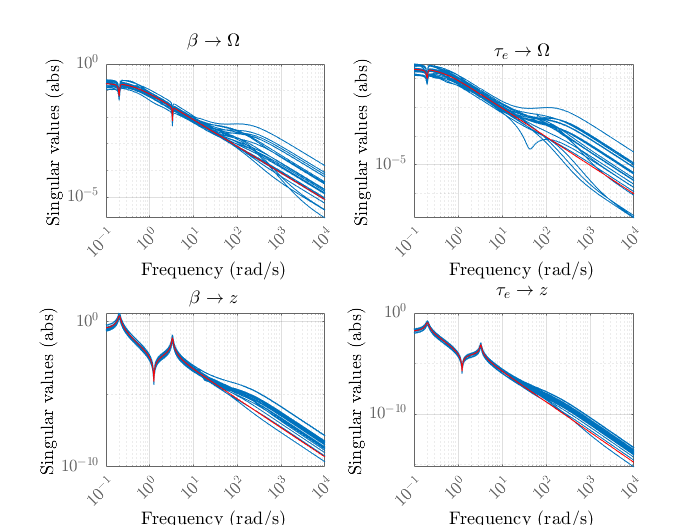

set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch4_uncertain_dynamics.eps',  'epsc')

warning on;


musyn

opts = musynOptions('MixedMU','off','FullDG',false,'MaxIter',20, ...
        'UseParallel', true, 'Display', 'short');
[K,clp,dkinfo] = musyn(P_w_D,2,2, opts);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           16.04        11.56        11.68            16
    2           6.322        6.189        6.212            12
    3           1.733        1.594        1.614            34
    4           1.187        1.186         1.22            34
    5           1.151         1.15         1.16            36
    6           1.142        1.139        1.149            38
    7            1.14        1.138        1.144            38
    8           1.137        1.135        1.278            34

Best achieved robust performance: 1.14





% omega = logspace(-10,10,800);
% opt = dkitopt('FrequencyVector', omega, 'DisplayWhileAutoIter', 'off');
% [K,clp,dkinfo] = dksyn(P_w_D,2,2, opt);
% dkinfo

K.InputName = {'v_(1)';'v_(2)'};
K.OutputName = {'u_(1)'; 'u_(2)'};

evalN

N_inputnames = {'u_1d(1)'; 'u_1d(2)'; 'u_2d(1)'; 'u_2d(2)'; 'w_(1)'; 'w_(2)';};
N_outputnames = {'y_1d(1)'; 'y_1d(2)'; 'y_2d(1)';'y_2d(2)';'z_1(1)'; 'z_1(2)';'z_2(1)'; 'z_2(2)'};

tf_y_v = 1;

N = connect(G, tf_y_v*K, sum_plant_input, sum_plant_output, Wi, Wo, Wu, Wp, y_to_v,  N_inputnames, N_outputnames);
M = N(1:4, 1:4);

evalN(N)

all tf's are individually stable --> NS
Nominal stability: true (-0.000251) 
Points completed: 150/150
Nominal performance: true (0.808130) 
Points completed: 150/150
Robust stability: true (0.590391) 
Points completed: 150/150
Robust performance: false (1.137655) 


wcgain(N)

ans = struct with fields:
           LowerBound: 297.7001
           UpperBound: 297.7001
    CriticalFrequency: 560.4367


prepare for simulation

%simulate without uncertainty

K_ = K;
K_.InputName  = {'dOmega'; 'z (m)'};
K_.OutputName = FWT.InputName(1:2);
dOmega_sum = -sumblk('dOmega = r - Omega (rad/s)');

P_w_K_OutputName = {'r';'V (m/s)';'Omega (rad/s)';'z (m)'; 'Beta (deg)';'tau_e (Nm)'};
P_w_K_InputName = {'r';'V (m/s)'};

P_w_K = connect(FWT, dOmega_sum, -K_, P_w_K_InputName, P_w_K_OutputName);

%With uncertainty
G_ = FWT;
G_.InputName(1:2) = {'u_g(1)'; 'u_g(2)'};
G_.OutputName = {'y_g(1)'; 'y_g(2)'};

P_w_D_w_K_OutputName = {'r';'V (m/s)';'y_g(1)';'y_g(2)'; 'u_g(1)';'u_g(2)'};
P_w_D_w_K_InputName = {'r';'V (m/s)'};

%replace dOmega_sum_ and use the input channel w_ for reference
%this is possible as it acts one the same signal 
sum_plant_output_ = sum_plant_output(:,1:end-1);
sum_plant_output_.InputName(end) = {'r'};
sum_plant_output_(1,end) =-1;

P_w_D_w_K = connect(G_, K, Delta, sum_plant_input, sum_plant_output_, ...
    Wi, Wo, Wu, Wp, y_to_v,  P_w_D_w_K_InputName, P_w_D_w_K_OutputName);


P_w_D_w_K.OutputName(5:6) = FWT.InputName(1:2); %rename u_(1), u_(2) back to \beta, \tau
P_w_D_w_K.OutputName(3:4) = FWT.OutputName; %rename v_(1), v_(2) back to \beta, \tau


check whether the plants are set up correctly

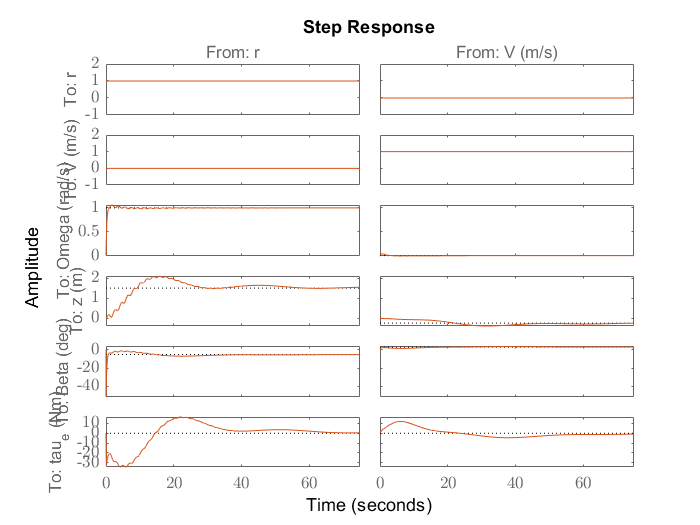

figure()
step(P_w_D_w_K.nominal, 75); hold on; %variant 1
step(P_w_K,75); %variant 2


%results in equivalent plots

plot uncertain and nominal response:

clf

MMIO = struct with fields:
           GainMargin: [0.5776 1.7314]
          PhaseMargin: [-29.9815 29.9815]
           DiskMargin: 0.5356
           LowerBound: 0.5356
           UpperBound: 0.5367
    CriticalFrequency: 0.3159
    WorstPerturbation: [1×1 struct]


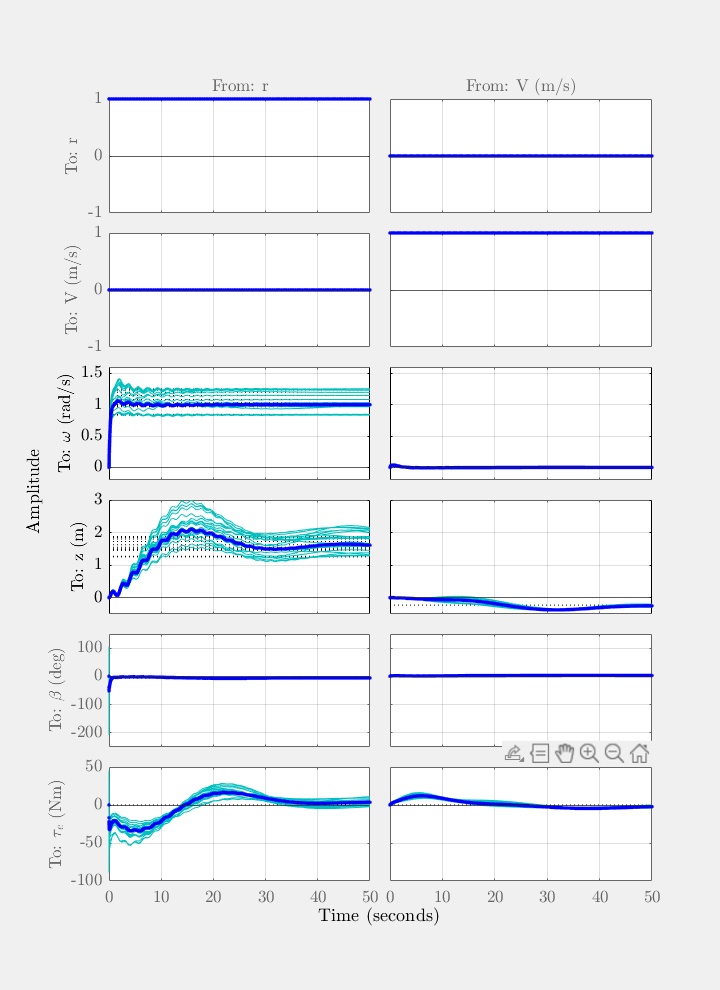

figsize = [0,0,6,4 *6];
f = figure('units','inch','position',figsize);


latex_step(P_w_D_w_K, '', 50, 'c-'); hold on;
latex_step(P_w_K, '',50, 'b.');

%format plot
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');
for i_ax_input = [6,7,12,13]
    yline(axs(i_ax_input), 0);
    %axs(i_ax_input).YColor='Blue';
end
for i_ax_output = [4,5,11,10]
    yline(axs(i_ax_output), 0);
    axs(i_ax_output).YColor='Black';
end
for i_ax_control = [3,2,8,9]
    yline(axs(i_ax_control), 0);
    %axs(i_ax_control).YColor='Magenta';
end

set(f,'Visible','on');
%saveas(gcf, 'Figures/dk_sim.png', 'Resolution',500);
% posF = f.Position; 
% set(f,'position',[posF(1),posF(2),posF(3),1.5*posF(4)])

exportgraphics(f,'Figures/dk_sim.png','Resolution',600)

plot sensitivity analysis

%Plant with Delta and Controller, w as input:
P_w_D_w_K_2 = connect(P_w_D,K, {'w_(1)'; 'w_(2)'}, {'v_(1)'; 'v_(2)'});

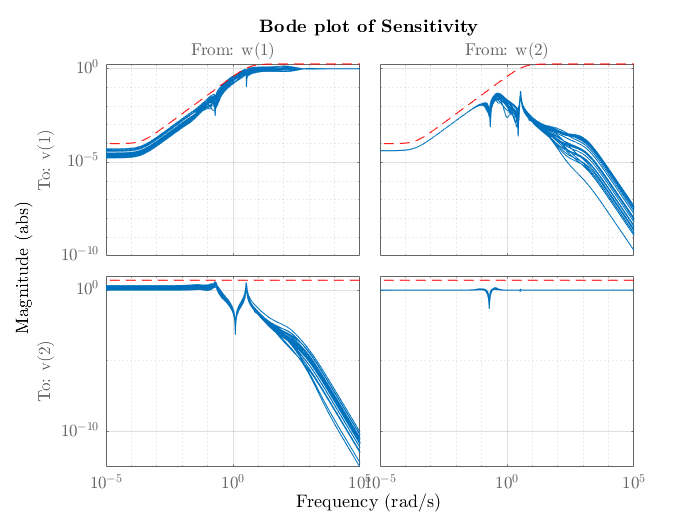

P_w_D_w_K_2.InputName = replace(P_w_D_w_K_2.InputName, "_","");
P_w_D_w_K_2.OutputName = replace(P_w_D_w_K_2.OutputName, "_","");

figure()
bodemag(P_w_D_w_K_2); hold on;

warning off
Wp_ = Wp;
Wp_(1,1) = inv(Wp(1,1));
Wp_(1,2) = inv(Wp(1,1));
Wp_(2,1) = inv(Wp(2,2));
Wp_(2,2) = inv(Wp(2,2));
warning on;

latex_bodemag(Wp_,"Sensitivity", ['red', '--'])

set(gcf,'renderer','painters');
saveas(gcf, 'Figures/dk_sensitivity.eps',  'epsc');

wcgain(P_w_D_w_K_2)

ans = struct with fields:
           LowerBound: 4.6746
           UpperBound: 4.6831
    CriticalFrequency: 0.1236


robgain(P_w_D_w_K_2,1)

ans = struct with fields:
           LowerBound: 0
           UpperBound: 0
    CriticalFrequency: NaN


MMIO = wcdiskmargin(G,K)

MMIO = struct with fields:
           GainMargin: [0.5776 1.7314]
          PhaseMargin: [-29.9815 29.9815]
           DiskMargin: 0.5356
           LowerBound: 0.5356
           UpperBound: 0.5367
    CriticalFrequency: 0.3159
    WorstPerturbation: [1×1 struct]
